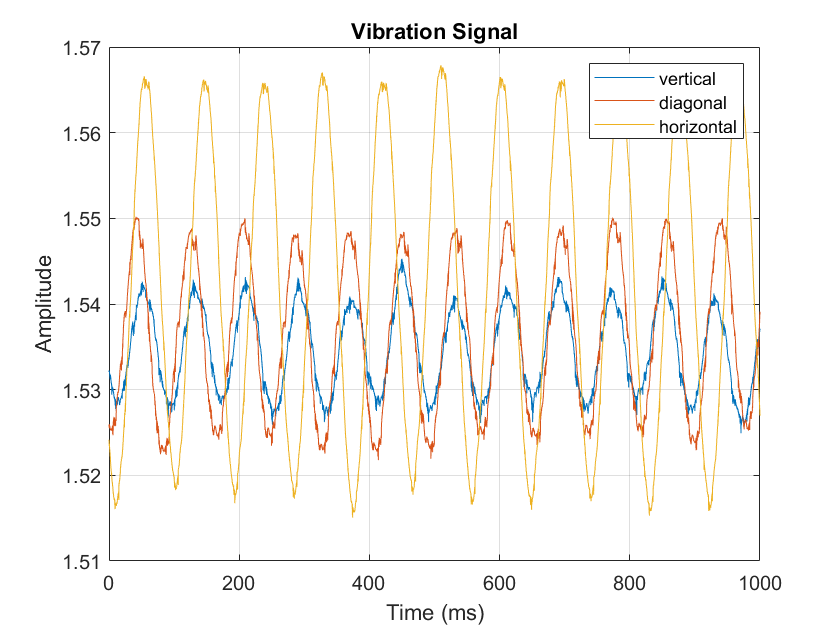


% Parameters
timeLimits = [0 0.1]; % seconds
t = linspace(0,1000, 10001);

%%
vertical_empty_z_ROI = vertical_empty_z(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(vertical_empty_z_ROI)-1))+1;
vertical_empty_z_ROI = vertical_empty_z_ROI(minIdx:maxIdx);

%%
diagonal_empty_z_ROI = diagonal_empty_z(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(diagonal_empty_z_ROI)-1))+1;
diagonal_empty_z_ROI = diagonal_empty_z_ROI(minIdx:maxIdx);

%%
empty_bottle_1_ROI = empty_bottle_1(:);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(empty_bottle_1_ROI)-1))+1;
empty_bottle_1_ROI = empty_bottle_1_ROI(minIdx:maxIdx);

plot(t,vertical_empty_z_ROI,t,diagonal_empty_z_ROI,t,empty_bottle_1_ROI)

grid on
legend('vertical', 'diagonal', 'horizontal')
title('Vibration Signal')
ylabel('Amplitude')
xlabel('Time (ms)')